## Creating symbolic variable and symbolic expression:

syms x t 
syms a b c
y=sin(x)

$$y = \sin\left(x\right)$$

f=a*x^2+b*x+c

$$f = a\,x^{2}+b\,x+c$$

g=exp(t)+sin(t)+sin(t^2)+2*cos(3*t)

$$g = 2\,\cos\left(3\,t\right)+\sin\left(t^{2}\right)+{\mathrm{e}}^{t}+\sin\left(t\right)$$


f=exp(t+1)

$$f = {\mathrm{e}}^{t+1}$$

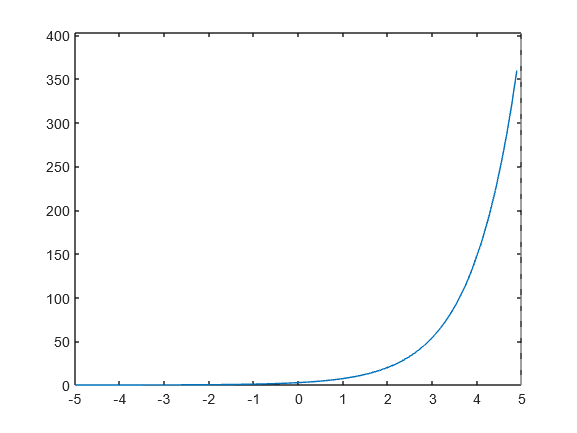

%to plot a symbolic function we use a function named fplot
fplot(f)

fplot(f,[-15,15])

xlabel('time')
ylabel('energy')


### Exercise :

expr=x^2+5*x+6

$$expr = x^{2}+5\,x+6$$

y=a*x^2+b*x+c

$$y = a\,x^{2}+b\,x+c$$

ylinear=(3*x/2)+4

$$ylinear = \frac{3\,x}{2}+4$$

ycubic=(x^3/2)-2*x+3

$$ycubic = \frac{x^{3}}{2}-2\,x+3$$

hold on
fplot(ylinear)
fplot(ycubic,[-1,3])
hold off

xlabel('x-axis')
ylabel("y-axis")

legend("linear-eq","cubic-eq")

## Differentiation:

% clear
syms x
y=3*x^2+2*x+1

$$y = 3\,x^{2}+2\,x+1$$

d_f1=diff(y,x)

$$d\_f1 = 6\,x+2$$

f_f2=diff(y,x,2)%a second order derivative(double differentiation

$$f\_f2 = 6$$

g=exp(x)*cos(2*x)

$$g = \cos\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g1=diff(g,x)

$$g1 = \cos\left(2\,x\right)\,{\mathrm{e}}^{x}-2\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g2=diff(g,x,2)

$$g2 = -3\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}-4\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g10=diff(g,x,10)

$$g10 = 237\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}+3116\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

subs(g10,x,2)

$$ans = 237\,\cos\left(4\right)\,{\mathrm{e}}^{2}+3116\,{\mathrm{e}}^{2}\,\sin\left(4\right)$$

vpa(subs(g10,x,2))

$$ans = -18569.511611620144360021052665075$$

t2=atan(x)

$$t2 = \mathrm{atan}\left(x\right)$$

y_x=diff(t2,x)

$$y\_x = \frac{1}{x^{2}+1}$$

subs(y_x,x,1)

$$ans = \frac{1}{2}$$

### Excercise 2:

t1=x^3

$$t1 = x^{3}$$

t2=diff(t1,x)

$$t2 = 3\,x^{2}$$

t1=sin(5*x)

$$t1 = \sin\left(5\,x\right)$$

y_x=diff(t1,x)

$$y\_x = 5\,\cos\left(5\,x\right)$$

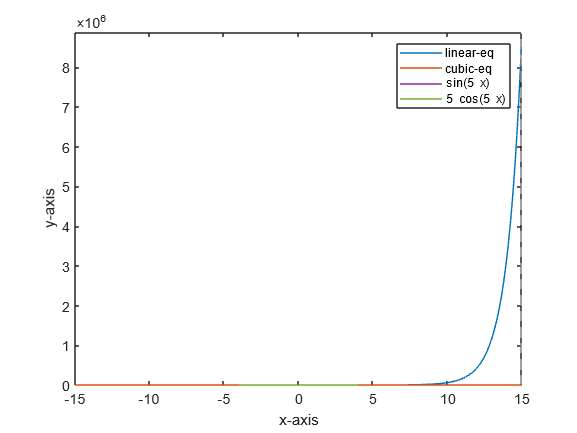


hold on
fplot(t1,[-4,4])
fplot(y_x,[-4,4])
hold off




f=exp(x)*cos(x)

$$f = {\mathrm{e}}^{x}\,\cos\left(x\right)$$

f1=diff(f,x)

$$f1 = {\mathrm{e}}^{x}\,\cos\left(x\right)-{\mathrm{e}}^{x}\,\sin\left(x\right)$$

f_2=subs(f1,x,2)

$$f\_2 = \cos\left(2\right)\,{\mathrm{e}}^{2}-{\mathrm{e}}^{2}\,\sin\left(2\right)$$

f=diff(sin(x^2))

$$f = 2\,x\,\cos\left(x^{2}\right)$$

vpa(subs(f,x,2))

$$ans = -2.614574483454447658556672732391$$

$$f = \sqrt{\sin\left(2\,x\right)+1}$$

$$m\_f = \frac{x^{9}}{362880}+\frac{x^{8}}{40320}-\frac{x^{7}}{5040}-\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}-\frac{x^{3}}{6}-\frac{x^{2}}{2}+x+1$$

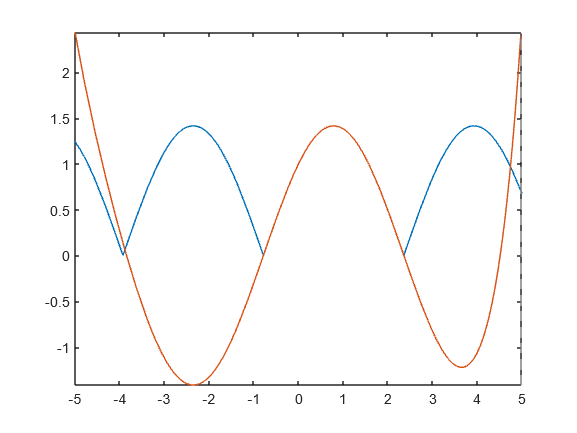

$$g = {\mathrm{e}}^{x}$$

$$h = \frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

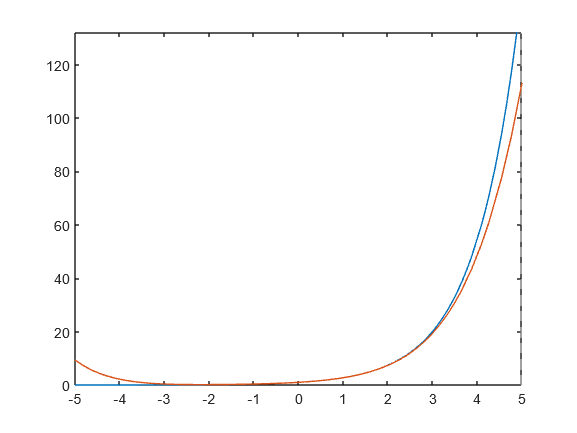

$$g = \cos\left(x\right)$$

$$g2 = -\frac{x^{10}}{3628800}+\frac{x^{8}}{40320}-\frac{x^{6}}{720}+\frac{x^{4}}{24}-\frac{x^{2}}{2}+1$$

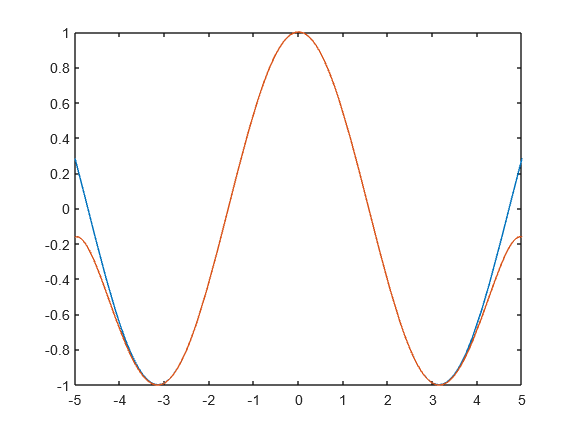

$$g = \sin\left(x\right)$$

$$g2 = \frac{x^{9}}{362880}-\frac{x^{7}}{5040}+\frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

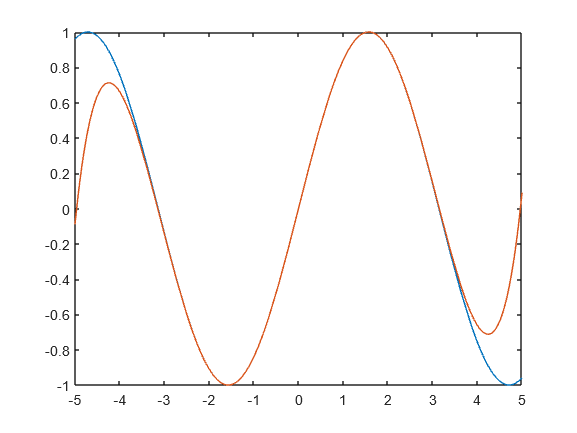

$$z = x^{3}+3\,x\,y+y^{3}$$

$$z\_x = 3\,x^{2}+3\,y$$

$$z\_y = 3\,y^{2}+3\,x$$

$$z\_x2 = 6\,x$$

$$z\_y2 = 6\,y$$

$$z\_xy = 3$$

$$u = y+\frac{x^{2}+y^{2}}{x}$$

$$ux = 2-\frac{x^{2}+y^{2}}{x^{2}}$$

$$uy = \frac{2\,y}{x}+1$$

$$uxy = -\frac{2\,y}{x^{2}}$$

$$uyx = -\frac{2\,y}{x^{2}}$$

% % 